clear;
clc;

Kernel + Test

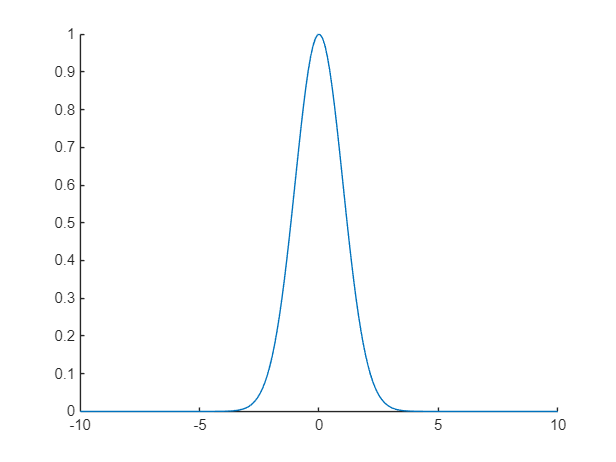

function K = Squared_Exponential_Kernel(sigma2, length, x1, x2)
    K = sigma2*exp(-(pdist2(x1,x2,"euclidean").^2)/(2*length^2));
    return
end
SE_Kernel_test_x = linspace(-10,10,200)';
SE_Kernel_test_length = 1;
SE_Kernel_test_sigma2 = 1;
SE_Kernel_test_k = Squared_Exponential_Kernel(SE_Kernel_test_sigma2,SE_Kernel_test_length,SE_Kernel_test_x,0);
figure;
hold on;
plot(SE_Kernel_test_x,SE_Kernel_test_k);

clear SE_Kernel_test_x SE_Kernel_test_k SE_Kernel_test_length SE_Kernel_test_sigma2;

Gaussian Proccess Regression

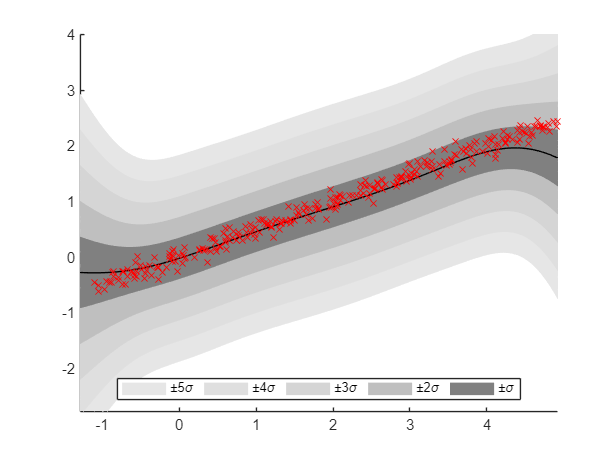

function C = Calculate_Covariance_Matrix(x, y)
    covariance_matrix = zeros(length(x),length(y));
    y_range = 1:length(y);
    parfor i = 1:length(x)
        for j = y_range
            covariance_matrix(i,j) = Squared_Exponential_Kernel(1,1,x(i),y(j));
        end
    end
    C = covariance_matrix;
    return
end
function [mean_at_values, covar_matrix, variance] = Gaussian_Proccess_Regression(data_x, data_y, at)
    noise = 10;
    K = Calculate_Covariance_Matrix(data_x,data_x)+ ...
        (noise+3e-6)*eye(length(data_x));
    K_star = Calculate_Covariance_Matrix(data_x,at);
    K_star2 = Calculate_Covariance_Matrix(at,at);
    mean_at_values = K_star'/K*data_y;
    covar_matrix = K_star2 - K_star'/K*K_star;
    variance = diag(covar_matrix);
    return
end
% x_values = [0,0.3,1,3.1,4.7]';
% y_values = [1,0,1.4,0,-0.9]';
n = 300;
true_x = linspace(-1,5,n)';
true_y = 0.5*true_x;
x_values = true_x+normrnd(0,0.1,n,1);
y_values = true_y+normrnd(0,0.1,n,1);
at_values = linspace(-5,10,250);
[mean, covariance, variance] = Gaussian_Proccess_Regression(x_values,y_values,at_values);
figure;
hold on;
x_fillplot = [at_values, fliplr(at_values)];
for i = 5:-1:1
    pm_sigma = [mean'+i*sqrt(variance'),fliplr(mean'-i*sqrt(variance'))];
    fill(x_fillplot,pm_sigma,[1-0.5/i,1-0.5/i,1-0.5/i],'LineStyle','none')
end
plot(at_values,mean,'k-');
scatter(x_values,y_values,'rx');
ylim([-6,6]);
xlim([-3,8]);
legend('\pm5\sigma','\pm4\sigma','\pm3\sigma','\pm2\sigma','\pm\sigma','Orientation','Horizontal','Location','South')